# 旋转多边形

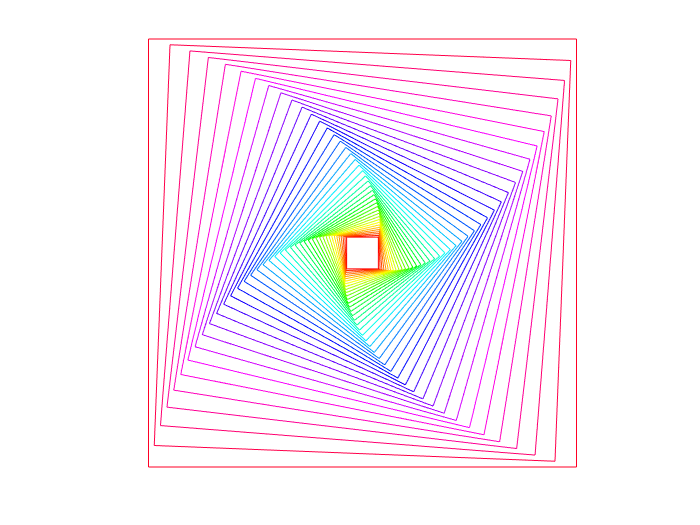

function V = SpiralPolygon(m, n, d_angle, rotate, shift)
th = linspace(0, 360, m + 1) + rotate;
V = [cosd(th); sind(th)];
C = colormap(hsv(n));
scale = sind(150 - abs(d_angle))/sind(30);
R = Rot2(d_angle);
% hold off
for i = 1:n
    if i > 1
        V = scale * R * V;
    end
    plot(V(1,:) + shift(1), V(2,:) + shift(2), 'Color', C(i,:));
    hold on
end
set(gcf, 'Color', 'w');
axis equal
axis off


function R = Rot2(theta)
theta = theta*pi/180;
R = [cos(theta), -sin(theta); sin(theta), cos(theta)];